wellID = 1;
numSeconds = 0.8;
resolution = 10;
samplingFrequency = 20000;
startSample = 1;
highPassCutOff = 1;
bandwidth = [950 1000];
correctionFactor = 2;

controlMedia = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000011/data.raw.h5'

controlMedia = '/home/mxwbio/Data/26/01/15_JG_Neurons/260115/P003375/ActivityScan/000011/data.raw.h5'

rawData_controlMedia = mxw.fileManager(controlMedia,wellID);

control_H21 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003387/ActivityScan/000026/data.raw.h5'

control_H21 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260116/P003387/ActivityScan/000026/data.raw.h5'

rawData_control_H21 = mxw.fileManager(control_H21,wellID);

control_H48 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260117/P003375/ActivityScan/000032/data.raw.h5'

control_H48 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260117/P003375/ActivityScan/000032/data.raw.h5'

rawData_control_H48 = mxw.fileManager(control_H48,wellID);

control_H72 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260118/P003425/ActivityScan/000037/data.raw.h5'

control_H72 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260118/P003425/ActivityScan/000037/data.raw.h5'

rawData_control_H72 = mxw.fileManager(control_H72,wellID);

control2H96 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260119/P003387/ActivityScan/000042/data.raw.h5'

control2H96 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260119/P003387/ActivityScan/000042/data.raw.h5'

rawData_control_H96 = mxw.fileManager(control2H96,wellID);

control2H120 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260120/P003387/ActivityScan/000047/data.raw.h5'

control2H120 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260120/P003387/ActivityScan/000047/data.raw.h5'

rawData_control_H120 = mxw.fileManager(control2H120,wellID);

control_H144 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260121/P003425/ActivityScan/000052/data.raw.h5'

control_H144 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260121/P003425/ActivityScan/000052/data.raw.h5'

rawData_control_H144 = mxw.fileManager(control_H144,wellID);

control2H168 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260122/P003425/ActivityScan/000058/data.raw.h5'

control2H168 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260122/P003425/ActivityScan/000058/data.raw.h5'

rawData_control_H168 = mxw.fileManager(control2H168,wellID);

control2H192 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260123/P003387/ActivityScan/000067/data.raw.h5'

control2H192 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260123/P003387/ActivityScan/000067/data.raw.h5'

rawData_control_H192 = mxw.fileManager(control2H192,wellID);

control2D14 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260129/P003387/ActivityScan/000073/data.raw.h5'

control2D14 = '/home/mxwbio/Data/26/01/15_JG_Neurons/260129/P003387/ActivityScan/000073/data.raw.h5'

rawData_control_D14 = mxw.fileManager(control2D14,wellID);

table_controlMedia = createActivityScanTable(rawData_controlMedia,startSample,numSeconds,0.5);
table_controlMedia = highPassFilterTraces(table_controlMedia,highPassCutOff,samplingFrequency);
[table_controlMedia, AvPSD_control2Media, Avfreq_control2Media] = calculatePSDs(table_controlMedia,samplingFrequency,resolution);

[RMS_control2Media] = calculateAverageRMS(AvPSD_control2Media,Avfreq_control2Media,bandwidth,resolution);
disp(RMS_control2Media);

   2.4128e-07




table_controlMedia = calculateRMSs(table_controlMedia, bandwidth,resolution);
table_controlMedia = calculateResistances(table_controlMedia, bandwidth);

%table_controlMedia = addSurfaceScanData(table_controlMedia,surfaceScan_controlMedia);

[table_controlH21,av1,diff1,~,~] = runAnalysis(rawData_control_H21,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_controlMedia,2);

   2.4006e-07



[table_controlH48,av2,diff2,~,~] = runAnalysis(rawData_control_H48,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_controlMedia,2);

   2.3935e-07



[table_controlH72,av3,diff3,~,~] = runAnalysis(rawData_control_H72,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_controlMedia,2);

   2.3864e-07



[table_controlH96,av4,diff4,~,~] = runAnalysis(rawData_control_H96,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_controlMedia,2);

   2.3783e-07



[table_controlH120,av5,diff5,~,~] = runAnalysis(rawData_control_H120,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_controlMedia,2);

   2.3687e-07



[table_controlH144,av6,diff6,~,~] = runAnalysis(rawData_control_H144,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_controlMedia,2);

   2.3451e-07



[table_controlH168,av7,diff7,~,~] = runAnalysis(rawData_control_H168,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_controlMedia,2);

   2.3401e-07



[table_controlH192,av8,diff8,~,~] = runAnalysis(rawData_control_H192,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_controlMedia,2);

   2.3192e-07



[table_controlD14,av9,diff9,~,~] = runAnalysis(rawData_control_D14,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,table_controlMedia,1);

   2.2616e-07



clf;

loglog(Avfreq_control2Media,sqrt(diff1))


hold on
loglog(Avfreq_control2Media,sqrt(diff2))

hold off
hold on
loglog(Avfreq_control2Media,sqrt(diff3))

hold off
hold on
loglog(Avfreq_control2Media,sqrt(diff4))

hold off
hold on
loglog(Avfreq_control2Media,sqrt(diff5))

hold off
hold on
loglog(Avfreq_control2Media,sqrt(diff6))

hold off
hold on
loglog(Avfreq_control2Media,sqrt(diff7))

hold off
hold on
loglog(Avfreq_control2Media,sqrt(diff8))

hold off
hold on
loglog(Avfreq_control2Media,sqrt(diff9))

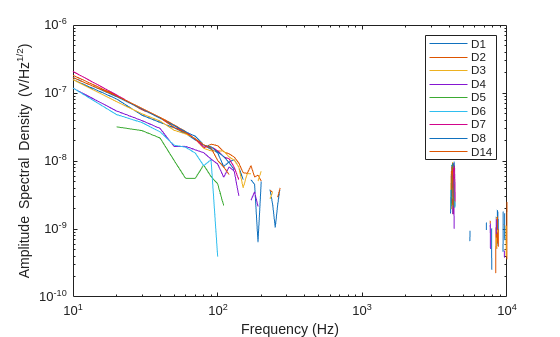

hold off

ax = gca;

xlabel(ax,'Frequency (Hz)');
ylabel(ax,'Amplitude Spectral Density (V/Hz^{1/2})');

legend('D1','D2','D3','D4','D5','D6','D7','D8','D14')

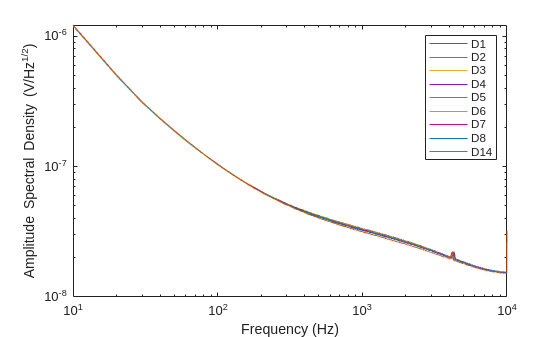

clf;

loglog(Avfreq_control2Media,sqrt(av1))

hold on
loglog(Avfreq_control2Media,sqrt(av2))
hold off
hold on
loglog(Avfreq_control2Media,sqrt(av3))
hold off
hold on
loglog(Avfreq_control2Media,sqrt(av4))
hold off
hold on
loglog(Avfreq_control2Media,sqrt(av5))
hold off
hold on
loglog(Avfreq_control2Media,sqrt(av6))
hold off
hold on
loglog(Avfreq_control2Media,sqrt(av7))
hold off
hold on
loglog(Avfreq_control2Media,sqrt(av8))
hold off
hold on
loglog(Avfreq_control2Media,sqrt(av9))
hold off
ax = gca;

xlabel(ax,'Frequency (Hz)');
ylabel(ax,'Amplitude Spectral Density (V/Hz^{1/2})');

legend('D1','D2','D3','D4','D5','D6','D7','D8','D14')

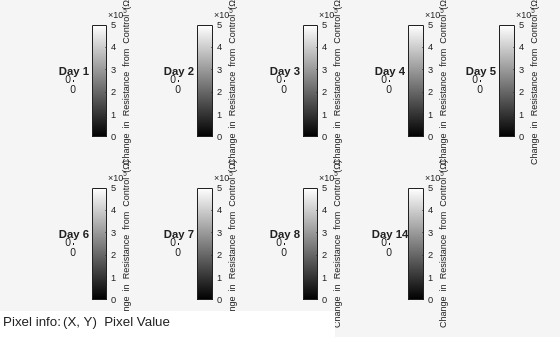

clf;
figure;
t = tiledlayout(2,5);
% nexttile;
% 
% ax = gca;
% 
% 
% Z = reshape(transpose(table_controlH14_5.diffResistances),220,120);
% 
% imagesc(ax,table_controlH14_5.xs,table_controlH14_5.ys,Z);
% impixelinfo;
% axis(ax,'equal');
% axis(ax,[0 2000 0 3850]);
% colormap(ax,gray);
% clim(ax,[0 500e3]);
% xlabel(ax,'X (\mum)');
% ylabel(ax,'Y (\mum)');
% 
% cb = colorbar(ax);
% cb.Label.String = 'Change in Resistance from Control (\Omega)';
% cb.Location = 'eastoutside';

nexttile;

ax = gca;


Z = reshape(transpose(table_controlH21.diffResistances),220,120);

imagesc(ax,table_controlH21.xs,table_controlH21.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');
title('Day 1')
cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;


Z = reshape(transpose(table_controlH48.diffResistances),220,120);

imagesc(ax,table_controlH48.xs,table_controlH48.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');
title('Day 2')
cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';
nexttile;

ax = gca;


Z = reshape(transpose(table_controlH72.diffResistances),220,120);

imagesc(ax,table_controlH72.xs,table_controlH72.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');
title('Day 3')
cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;


Z = reshape(transpose(table_controlH96.diffResistances),220,120);

imagesc(ax,table_controlH96.xs,table_controlH96.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);

xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');
title('Day 4')
cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;


Z = reshape(transpose(table_controlH120.diffResistances),220,120);

imagesc(ax,table_controlH120.xs,table_controlH120.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);
title('Day 5')
xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;


Z = reshape(transpose(table_controlH144.diffResistances),220,120);

imagesc(ax,table_controlH144.xs,table_controlH144.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);
title('Day 6')
xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;


Z = reshape(transpose(table_controlH168.diffResistances),220,120);

imagesc(ax,table_controlH168.xs,table_controlH168.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);
title('Day 7')
xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

nexttile;

ax = gca;


Z = reshape(transpose(table_controlH192.diffResistances),220,120);

imagesc(ax,table_controlH192.xs,table_controlH192.ys,Z);
impixelinfo;
axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);
title('Day 8')
xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';


nexttile;

Z = reshape(transpose(table_controlD14.diffResistances),220,120);
ax = gca;
imagesc(ax,table_controlD14.xs,table_controlD14.ys,Z);

axis(ax,'equal');
axis(ax,[0 2000 0 3850]);
colormap(ax,gray);
clim(ax,[0 500e3]);
title('Day 14')
xlabel(ax,'X (\mum)');
ylabel(ax,'Y (\mum)');

cb = colorbar(ax);
cb.Label.String = 'Change in Resistance from Control (\Omega)';
cb.Location = 'eastoutside';

function T = createSerialRecordingTable(rawData,startSample,numSeconds,correctionFactor,recordingNum)
        

        numSamples = numSeconds*rawData.fileObj(1).samplingFreq;
        [electrodeNums, xs,ys] = calculateXYCoords(rawData);
        
        rawTraces = zeros(length(electrodeNums),numSamples);
        hasTraces = false(length(electrodeNums),1);

        T = table(electrodeNums,hasTraces,xs,ys,rawTraces);
        
        [rawTracesInScan,~,electrodesInScan] = rawData.extractRawData(startSample,numSamples,'file',recordingNum);
        electrodesInScan = transpose(cell2mat(electrodesInScan));

        rawTracesInScan = transpose((rawTracesInScan./(1E6))*correctionFactor);
        [inTable, location] = ismember(T.electrodeNums, electrodesInScan);
        T.rawTraces(inTable,:) = rawTracesInScan(location(inTable),:);
        T.hasTraces(inTable) = true;
     
end

function T = createActivityScanTable(rawData,startSample,numSeconds,correctionFactor)
        

        numSamples = numSeconds*rawData.fileObj(1).samplingFreq;
        [electrodeNums, xs,ys] = calculateXYCoords(rawData);
        
        rawTraces = zeros(length(electrodeNums),numSamples);
        hasTraces = false(length(electrodeNums),1);

        T = table(electrodeNums,hasTraces,xs,ys,rawTraces);
        
        n = rawData.nRecordings;

        for recordingNum = 1:n
            [rawTracesInScan,~,electrodesInScan] = rawData.extractRawData(startSample,numSamples,'file',recordingNum);
            electrodesInScan = transpose(cell2mat(electrodesInScan));

            rawTracesInScan = transpose((rawTracesInScan./(1E6))*correctionFactor);
            [inTable, location] = ismember(T.electrodeNums, electrodesInScan);
            T.rawTraces(inTable,:) = rawTracesInScan(location(inTable),:);
            T.hasTraces(inTable) = true;

        end
     
end




function T = createFullElectrodeTable(rawData)

           [electrodeNums, xs, ys] = calculateXYCoords(rawData);
           
           T = table(electrodeNums,xs,ys);
 
end

function T = addSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    T = addvars(T,scanT.Var2,'NewVariableNames','surfaceScanVals');

end

function T = calculateDifferentialSurfaceScanData(T,scanT)

    scanT = sortrows(scanT);
    scanT = scanT(scanT.Var2 > 0 & scanT.Var2 <= 100,:);
    diffVals = T.surfaceScanVals - scanT.Var2;

    T = addvars(T,diffVals,'NewVariableNames','diffSurfaceScanVals');

end

    
function T = highPassFilterTraces(T, highPassCutOff,samplingFreq)
        
        [sos,g] = butter(1,highPassCutOff/(samplingFreq/2),"high");
        filteredTraces = filtfilt(sos,g,double(transpose(T.rawTraces)));
        T = addvars(T,transpose(filteredTraces),'NewVariableNames','filteredTraces');
        
end

function [T, avPSD, avFreq] = calculatePSDs(T,samplingFreq,resolution)
    
        

        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        [PSDs,frequencies] = pwelch(transpose(T.filteredTraces),window,overlap,nfft,samplingFreq);
        
        
        avPSD = sum(PSDs,2)/(sum(T.hasTraces)); 

        avFreq = frequencies;

        frequencies = repmat(frequencies,1,size(PSDs,2));
        PSDs = transpose(PSDs);
        frequencies = transpose(frequencies);

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  
        
end

function [T, avPSD, avFreq] = calculateSubsetPSDs(T,samplingFreq,resolution,numElectrodes)

        overlap = 0;    
        nfft = samplingFreq / resolution;
        window = hann(nfft);

        PSDs = zeros(height(T),((nfft/2)+1));
        frequencies = zeros(height(T),((nfft/2)+1));

        T = addvars(T,PSDs,frequencies,'NewVariableNames',{'PSDs', 'frequencies'});  

        electrodesCount = 0;
    
        for i=1:height(T)
            if (T.hasTraces(i)) && (electrodesCount <= numElectrodes)

                [T.PSDs(i,:),T.frequencies(i,:)] = pwelch(T.filteredTraces(i,:),window,overlap,nfft,samplingFreq);
                electrodesCount = electrodesCount + 1;
                frequencies = T.frequencies(i,:);
            end
        end

        avPSD = sum(T.PSDs,1)/numElectrodes; 

        avFreq = frequencies;

end




function [T,avDiffPSD] = calculateDifferentialPSDs (T,controlT)

        differentialPSDs = transpose(T.PSDs) - transpose(controlT.PSDs);

        avDiffPSD = sum(differentialPSDs,2)/sum(T.hasTraces);

        T = addvars(T, transpose(differentialPSDs), 'NewVariableNames','diffPSDs');
    
end

function avRMS = calculateAverageRMS(avPSD,avFreq,bandwidth, resolution)

        

        bandwidth = bandwidth./resolution;
        f = avFreq(bandwidth(1):bandwidth(2));
        PSD = avPSD(bandwidth(1):bandwidth(2));

        avRMS = sqrt(trapz(f,PSD));

end




function T = calculateRMSs(T,bandwidth,resolution)

        bandwidth = bandwidth./resolution;
        len = height(T);
        RMSs = zeros(len, 1);
        variances = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            PSD = transpose(T.PSDs(i,bandwidth(1):bandwidth(2)));
            RMSs(i) = sqrt(trapz(f,PSD)); 
            variances(i) = trapz(f,PSD); 
        end

        T = addvars(T, RMSs,variances,'NewVariableNames',{'RMSs','variances'});

end

function T = calculateDifferentialRMSs(T,bandwidth,resolution)

        bandwidth = bandwidth./resolution;
        len = height(T);
        diffVariances = zeros(len, 1);
        diffRMSs = zeros(len, 1);

        for i = 1:len
            f = transpose(T.frequencies(i,bandwidth(1):bandwidth(2)));
            diffPSD = transpose(T.diffPSDs(i,bandwidth(1):bandwidth(2)));
            diffRMSs(i) = sqrt(trapz(f,diffPSD)); 
            diffVariances(i) = trapz(f,diffPSD); 
        end

        T = addvars(T, diffRMSs,diffVariances, 'NewVariableNames',{'diffRMSs','diffVariances'});

end

function T = calculateResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        resistances = (transpose(T.variances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(resistances), 'NewVariableNames','resistances');

end


function T = calculateDifferentialResistances (T,bandwidth)
        
        boltzman = 1.38E-23;
        temp = 310;

        diffResistances = (transpose(T.diffVariances))./(4*boltzman*temp*(bandwidth(2)-bandwidth(1)));
        T = addvars(T, transpose(diffResistances), 'NewVariableNames','diffResistances');

end

function [electrodeNums, xs, ys] = calculateXYCoords(rawData)

        recordingElectrodes = rawData.processedMap.electrode();
        unroutedElectrodes = rawData.processedMap.nonRoutedElec();

        electrodeNums = cat(1,recordingElectrodes,unroutedElectrodes);
        electrodeNums = sort(electrodeNums);
        
        len = length(electrodeNums);
        
        xs = zeros(1,len);
        ys = zeros(1,len);
        
        for i = 1:len
            ys(i) = ceil(i/220) ;
            xs(i) = i - (220*(ys(i)-1));
            
        end

        W = 220; 

        x_rot = ys;
        y_rot = (W - 1) - xs;

        xs = x_rot;
        ys = y_rot;

       
        
        xs = transpose(xs*17.5);
        ys = transpose(ys*17.5);
end

function plotPowerSpectrum(controlAvFreqArray,controlAvPSDArray,tAvfreq,tAvPSD,nRecordings,endRecording,titlePlot,ylabelPlot)
        clf('reset');
        
        loglog(controlAvFreqArray,sqrt(controlAvPSDArray));
        hold on;
        loglog(tAvfreq,sqrt(tAvPSD));
        hold off;
        
        colorMapLength = nRecordings;
        red = [1,0,0];
        blue = [0,0,1];
        black = [0,0,0];
        
        
        colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
        colours_ctrl = black;
        ax=gca;
        ax.ColorOrder = cat(1,colours_scale,colours_ctrl);
        
        hours = linspace(0,endRecording,nRecordings)+3;
        legendText = cell(1,nRecordings+1);
        
        for i = 1:nRecordings
            legendText{i} = sprintf('Hour %g ',hours(i));
        end
        
        mediaLabel = 'Media Control';
        legendText{nRecordings+1} = mediaLabel;
        legend(string(transpose(legendText)))
        
        xlim([0 5000]);
        xlabel('Frequency (Hz)');
        ylabel(ylabelPlot);
        title(titlePlot);
        set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')
end

function plotPowerSpectrumDiff(controlAvFreqArray,controlAvPSDArray,nRecordings,endRecording,titlePlot,ylabelPlot)
        clf('reset');
        
        loglog(controlAvFreqArray,controlAvPSDArray);
        
        
        colorMapLength = nRecordings;
        red = [1,0,0];
        blue = [0,0,1];
        black = [0,0,0];
        
        
        colours_scale = [linspace(red(1),blue(1),colorMapLength)', linspace(red(2),blue(2),colorMapLength)', linspace(red(3),blue(3),colorMapLength)'];
        colours_ctrl = black;
        ax=gca;
        ax.ColorOrder = cat(1,colours_scale,colours_ctrl);
        
        hours = linspace(0,endRecording,nRecordings)+3;
        legendText = cell(1,nRecordings);
        
        for i = 1:nRecordings
            legendText{i} = sprintf('Hour %g ',hours(i));
        end
        
     
        legend(string(transpose(legendText)))
        
        xlim([100 3500]);
        xlabel('Frequency (Hz)');
        ylabel(ylabelPlot);
        title(titlePlot);
        set(gca,'xminorgrid','off','yminorgrid','off','xgrid','on','ygrid','on')
end

function generateMEAVideo(nRecordings,controlTableArray,filename)
        videoFile = filename;
        
        v = VideoWriter(videoFile, 'Uncompressed AVI');
        v.FrameRate = 2;         
        open(v);
        
        figure;
        set(gcf,'Position',[100 100 700 900], 'Color','w');              
        ax = axes('Position',[0.1 0.1 0.75 0.8]);
        
        
        hours = 1.5;          
        
        for i = 1:nRecordings
        
            cla(ax);
        
            Z = reshape(transpose(controlTableArray{i}.diffResistances),220,120);
        
            imagesc(ax,controlTableArray{i}.xs,controlTableArray{i}.ys,Z);
        
            axis(ax,'equal');
            axis(ax,[0 2000 0 3850]);
            colormap(ax,gray);
            clim(ax,[0 200e3]);
        
            xlabel(ax,'X (\mum)');
            ylabel(ax,'Y (\mum)');
                 
            cb = colorbar(ax);
            cb.Label.String = 'Change in Resistance from Control (\Omega)';
            cb.Location = 'eastoutside';
            
            t_hours = (i-1) * hours + 3;
            title(ax, sprintf('T = %.1f h', t_hours),'FontWeight','bold')
        
            drawnow        
            frame = getframe(gcf);
            writeVideo(v, frame);
        end
        
        close(v);
end


function [tableData, avPSD,avDiffPSD,avFreq,avRMS] = runAnalysis(rawData,startSample,numSeconds,highPassCutOff,samplingFrequency,resolution,bandwidth,controlTable,correctionFactor)

    tableData = createActivityScanTable(rawData, startSample,numSeconds,correctionFactor);
    tableData = highPassFilterTraces(tableData,highPassCutOff,samplingFrequency);
    
    [tableData, avPSD, avFreq] = calculatePSDs(tableData,samplingFrequency,resolution);
    [tableData,avDiffPSD] = calculateDifferentialPSDs(tableData,controlTable);
    
    tableData = calculateDifferentialRMSs(tableData, bandwidth,resolution);
    tableData = calculateDifferentialResistances(tableData, bandwidth);
    
    [avRMS] = calculateAverageRMS(avPSD,avFreq,bandwidth,resolution);
    disp(avRMS);
    
    tableData = calculateRMSs(tableData, bandwidth,resolution);
    tableData = calculateResistances(tableData, bandwidth);
    
    tableData = removevars(tableData,["rawTraces","filteredTraces",'PSDs','diffPSDs','frequencies']);

    %tableData = addSurfaceScanData(tableData,surfaceScan_controlT60);
    %tableData = calculateDifferentialSurfaceScanData(tableData,surfaceScan_controlMedia);
end

